# INTERPOLACIÓ POLINOMICA

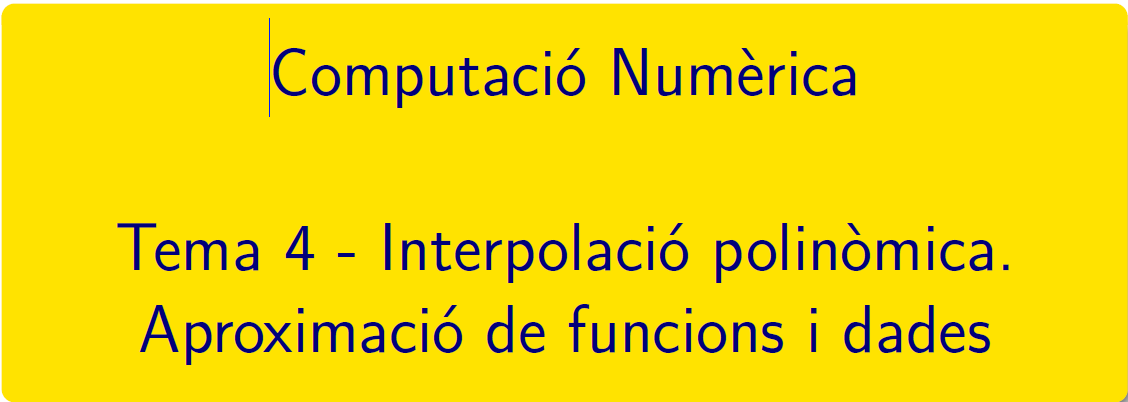

## APRENEM .....

### Polinomis i MATLAB®

Consulteu la pàgina [crear y evaluar polinomios](https://es.mathworks.com/help/matlab/math/create-and-evaluate-polynomials.html) y la pàgina [Raíces de polinomios](https://es.mathworks.com/help/matlab/ref/roots.html), ambdues de la documentació de MATLAB®. També us pot interesar la pàgina [Integrar y diferenciar polinomios](https://es.mathworks.com/help/matlab/math/integrate-and-differentiate-polynomials.html).

Després de llegir els dos primers documents, calculeu:

- les arrels del polinomi cúbic (grau 3)  $x^3+4x^2+4x=0$ 

p=[1 4 4 0];                       % vector amb els coeficients del polinomi 
r=roots(p); 
disp(['arrels = ', num2str(r')])   % arrels

- avalueu el polinomi  $x^5-1$ per $x=2$

p=[1 0 0 0 0 -1 ];                 % vector amb els coeficients del polinomi 
v=polyval(p,2); 
disp(['valor = ',num2str(v)])      % valor polinomi

- coficients del polinomi d'arrels els enters  -5,-2, -1, 1, 2, i 8. Quin grau té?

r=[-5,-2,-1,1,2,8 ];               % vector amb les arrels
c=poly(r); 
disp(['coeficients = ',num2str(c)])   % coeficients polinomi d'arrels r

### Polinomi interpolador

Baixeu-vos del campus el codi de polyinterp.m. Aquest codi és el que C. Moler explica en el chapter 3 dels seus apunts *"Numerical Computing with Matlab". *Consulteu la pàgina 5 i reproduïu el seu exemple. 

% x = 1:6;
% y = [16 18 21 17 15 12];
% disp([x; y])
% polyinterp(x,y,4.5)
% u = .75:.05:6.25;
% v = polyinterp(x,y,u);   
% plot(x,y,'o',u,v,'r-');

La rutina polyinterp.m s'obtenen els valors del polinomi interpolador a la taula [x;y] i permet fer la seva representació gràfica. En cap cas obtenim els coeficients del polinomi interpolador. 

#### Funcions de MATLAB® 

Els coeficients del polinomi interpolador es poden obtenir amb polyfit, i els valors aproximats amb polyval. Consulteu [polyfit](https://es.mathworks.com/help/matlab/ref/polyfit.html)

% x = 1:6;
% y = [16 18 21 17 15 12];
% disp([x; y])
% grau = length(x)-1
% p = polyfit(x,y,grau)  
% polyval(p,4.5)                         

**polyinterp de Moler = polyfit + polyval de MATLAB**

#### **Error en la interpolació polinòmica**

Baixeu-vos del campus el codi de rungeinterp.m. Aquest codi és el que C. Moler explica en el chapter 3 dels seus apunts *"Numerical Computing with Matlab". *Consulteu l'exercici 3.9 de la pàgina 23. 

- a) Experimenteu la interpolació de la funció f(x) per n=2,3,7,11,13,17,19,23,29 ... o altres valors en punts equiespaiats fent ús de rungeinterp.m i polyinterp.m

% rungeinterp()

Observeu: Per a quins x de l'interval [-1,1] és compleix $P_n(x) \rightarrow f(x)$ per $n \rightarrow \infty$?

- b) Experimenteu la interpolació de la funció f(x) per n=2,3,7,11,13,17,19,23,29 ... o altres valors fent en punts no EQUIESPAIATS fent ús de interp_gadget.m i polyinterp.m

% interp_gadget()

Observeu: Per a quin tipus d'abscises és compleix $P_n(x) \rightarrow f(x)$ per $n \rightarrow \infty$ per a tot x de l'interval [-1,1] ?

### Interpolació polinomial a trossos. 

% clearvars; 
% x = 1:6;
% y = [16 18 21 17 15 12];
% interpgui(x,y)

#### Diferències entre spline i pchip

% clearvars;
% x = 1: 8;
% y = zeros (1,8);
% y (4) = 1;
% interpgui(x, y)

#### Funcions de MATLAB® 

Per veure totes les possibilitats d'interpolació en MATLAB® consulteu la pàgina [interpolación](https://es.mathworks.com/help/matlab/interpolation.html) y més concretament la pàgina de la comanda [interp1](https://es.mathworks.com/help/matlab/ref/interp1.html), per obtenir un polinomi interpolador a trossos. Resum de de la comanda. 

## PRACTIQUEM ....

clearvars; clf

### 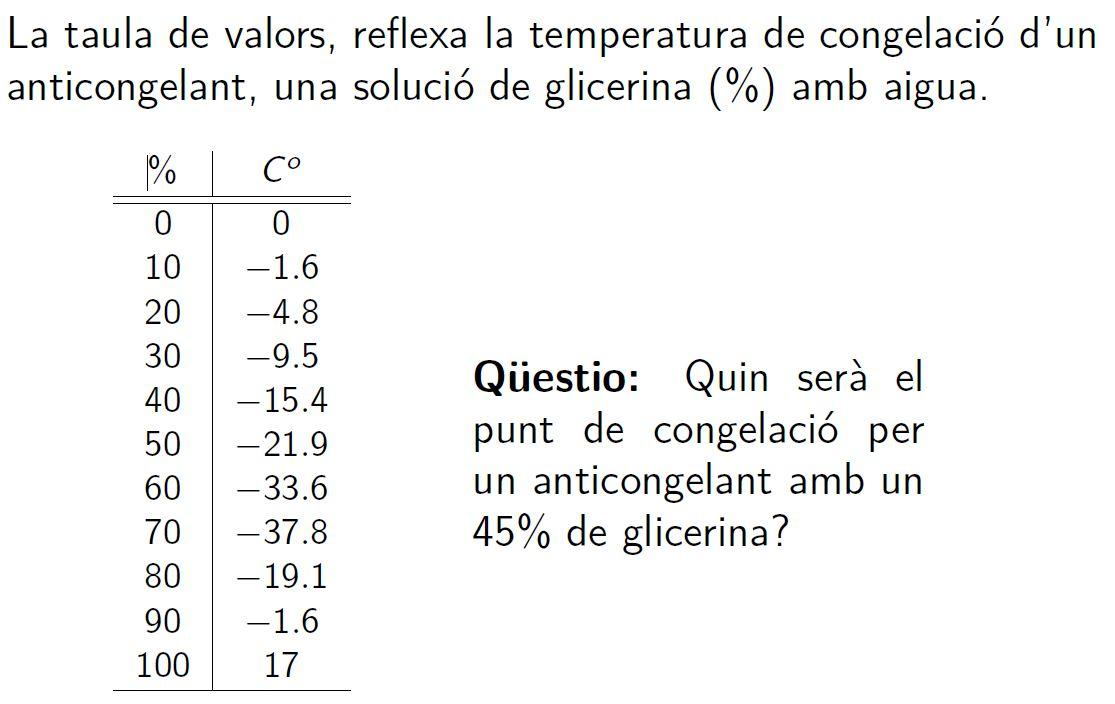

### Donar una estimació del punt de congelació per anticongelant amb **45%** de glicerol.

Aquest exercici s'ha de resoldre fent ús de **polyinterp**

- Gráfica de los datos

x=0:10:100; 
y=[0 -1.6 -4.8 -9.5 -15.4 -21.9 -33.6 -37.8 -19.1 -1.6 17];
plot(x,y,'*')

grid on
ylabel('Temperatura, ºC')
xlabel('% Glicerina')

#### Exercici 1. Interpolació lineal (recta)

- Valor aproximat polinomi

% x1=[40, 50];
% y1=[-15.4 -21.9];
% valor_p1_45=polyinterp(x1,y1,45)
% 
% disp(['valor = ',num2str(valor_p1_45)])

- Grafica de les dades, el valor aproximat i el polinomi interpolador

% z=[25:65]; 
% pz=polyinterp(x1,y1,z);
% plot(z,pz,x,y,'*b',45,valor_p1_45,'*r','LineWidth',2)
% 
% grid on
% ylabel('Temperatura, ºC')
% xlabel('% Glicerina')
% title('Recta')

#### Exercici 2. Polinomi interpolador de grau 3

- Valor aproximat polinomi

- Grafica de les dades, el valor aproximat i el polinomi interpolador

x=0:10:100; 
y=[0 -1.6 -4.8 -9.5 -15.4 -21.9 -33.6 -37.8 -19.1 -1.6 17];

#### Exercici 3. Polinomi interpolador de grau 10

- Valor aproximat polinomi

- Grafica de les dades, el valor aproximat i el polinomi interpolador

x=0:10:100; 
y=[0 -1.6 -4.8 -9.5 -15.4 -21.9 -33.6 -37.8 -19.1 -1.6 17];

#### Exercici 4. Spline lineal  (interpolació lineal a trossos)

- Valor aproximat polinomi

- Grafica de les dades, el valor aproximat i el polinomi interpolador

x=0:10:100; 
y=[0 -1.6 -4.8 -9.5 -15.4 -21.9 -33.6 -37.8 -19.1 -1.6 17];

#### Exercici 5. Spline cúbic  (interpolació cúbica a trossos)

- Valor aproximat polinomi

- Grafica de les dades, el valor aproximat i el polinomi interpolador

x=0:10:100; 
y=[0 -1.6 -4.8 -9.5 -15.4 -21.9 -33.6 -37.8 -19.1 -1.6 17];

#### Exercici 6. Ajust per mínims quadrats (recta)

- Valor aproximat recta

- Grafica de les dades, el valor aproximat i el polinomi interpolador

#### Exercici 7. Ajust per mínims quadrats (cúbica)

- Valor aproximat cúbica

- Grafica de les dades, el valor aproximat i el polinomi interpolador

function v = polyinterp(x,y,u)
%POLYINTERP  Polynomial interpolation.
%   v = POLYINTERP(x,y,u) computes v(j) = P(u(j)) where P is the
%   polynomial of degree d = length(x)-1 with P(x(i)) = y(i).

%   Copyright 2014 Cleve Moler
%   Copyright 2014 The MathWorks, Inc.

% Use Lagrangian representation.
% Evaluate at all elements of u simultaneously.

n = length(x);
v = zeros(size(u));
for k = 1:n
   w = ones(size(u));
   for j = [1:k-1 k+1:n]
      w = (u-x(j))./(x(k)-x(j)).*w;
   end
   v = v + w*y(k);
end
end